# Teoria delle strutture - PROBLEMA 4

% serbatoio pieno d'acqua schematizzato come guscio sottile
%% Clear workspace and close any open windows
clear all
close all

## SOLUZIONE PUNTO 1 & 2

% 1) Assumendo che il serbatoio possa essere schematizzato come un guscio sottile, scrivere
%l’equazione differenziale e le condizioni al bordo che permettono di determinare la soluzione
%di questo problema di equilibrio.

% 2) Determinare le espressioni dello spostamento trasversale e delle caratteristiche della
%sollecitazione (semplificare il problema relativamente al calcolo delle componenti flessionali
%della sollecitazione, assumendo nel calcolo che il guscio sia di lunghezza infinita).

## simbolico

syms z  A1 A2 E R nu t h gamma beta D real

p=-gamma*(h-z) % Carico idrostatico

$$p = -\gamma \,\left(h-z\right)$$

## Variabili numeriche

R_n=1000; % raggio serbatoio [mm]
E_n=210000; % Young's modulus steel [N/mm^2]
nu_n=0.3; % coefficiente di Poisson acciaio
t_n=R_n/50; % spessore serbatoio
h_n=5*R_n; % altezza serbatoio
gamma_n=0.000001; % peso specifico dell'acqua N/mm3
p_n=-gamma_n*(h_n-z); % Carico idrostatico
D_n=(E_n*t_n^3)/(12*(1-nu_n^2)); % rigidezza flessionale
beta_n=((E_n*t_n*R_n^2)/D_n)^(1/4);

## Soluzione omogenea

wo=A1*exp(-(beta*z)/(R*sqrt(2)))*cos((beta*z)/(R*sqrt(2)))... 
    +A2*exp(-(beta*z)/(R*sqrt(2)))*sin((beta*z)/(R*sqrt(2)))

$$wo = A_{1}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\cos\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)+A_{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\sin\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)$$

## Soluzione particolare

wp=(p*R^2)/(E*t)

$$wp = -\frac{R^{2}\,\gamma \,\left(h-z\right)}{\text{E}\,t}$$

## Soluzione

w(z)=wo+wp

$$w(z) = A_{1}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\cos\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)+A_{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\sin\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)-\frac{R^{2}\,\gamma \,\left(h-z\right)}{\text{E}\,t}$$

% Derivate
w_z(z)=diff(w,z) % derivata prima

$$w\_z(z) = \begin{array}{l} \frac{R^{2}\,\gamma }{\text{E}\,t}-\frac{\sqrt{2}\,A_{1}\,\beta \,{\mathrm{e}}^{-\sigma_{1}}\,\cos\left(\sigma_{1}\right)}{2\,R}+\frac{\sqrt{2}\,A_{2}\,\beta \,{\mathrm{e}}^{-\sigma_{1}}\,\cos\left(\sigma_{1}\right)}{2\,R}-\frac{\sqrt{2}\,A_{1}\,\beta \,{\mathrm{e}}^{-\sigma_{1}}\,\sin\left(\sigma_{1}\right)}{2\,R}-\frac{\sqrt{2}\,A_{2}\,\beta \,{\mathrm{e}}^{-\sigma_{1}}\,\sin\left(\sigma_{1}\right)}{2\,R}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\beta \,z}{2\,R} \end{array}$$

## Applico le Condizioni al contorno:

cc1=w(0)==0                          

$$cc1 = A_{1}-\frac{R^{2}\,\gamma \,h}{\text{E}\,t}=0$$

cc2=w_z(0)==0                 

$$cc2 = \frac{\sqrt{2}\,A_{2}\,\beta }{2\,R}-\frac{\sqrt{2}\,A_{1}\,\beta }{2\,R}+\frac{R^{2}\,\gamma }{\text{E}\,t}=0$$

## risolvo il sistema per trovare A1 e A2

S=solve([cc1 cc2],[A1 A2]);    
A_1=S.A1(1)

$$A\_1 = \frac{R^{2}\,\gamma \,h}{\text{E}\,t}$$

A_2=simplify(S.A2(1))

$$A\_2 = -\frac{R^{2}\,\gamma \,\left(\sqrt{2}\,R-\beta \,h\right)}{\text{E}\,\beta \,t}$$

## spostamento

w1(z)=simplify(subs(w,[A1 A2],[A_1 A_2]))

$$w1(z) = \begin{array}{l} \frac{R^{2}\,\gamma \,h\,{\mathrm{e}}^{-\sigma_{1}}\,\cos\left(\sigma_{1}\right)}{\text{E}\,t}-\frac{R^{2}\,\gamma \,\left(h-z\right)}{\text{E}\,t}-\frac{R^{2}\,\gamma \,{\mathrm{e}}^{-\sigma_{1}}\,\sin\left(\sigma_{1}\right)\,\left(\sqrt{2}\,R-\beta \,h\right)}{\text{E}\,\beta \,t}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\beta \,z}{2\,R} \end{array}$$

## soluzione numerica

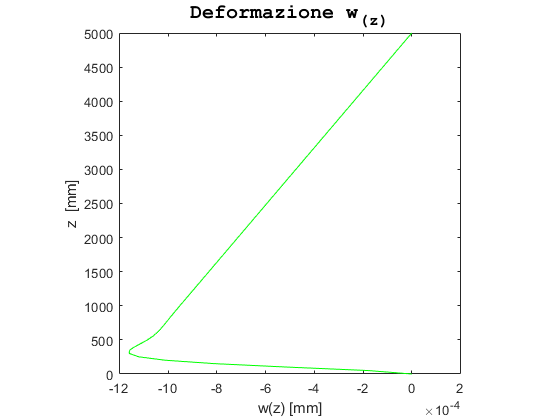

A_11=subs(A_1,[R gamma h E t],[R_n gamma_n h_n E_n t_n]);
A_22=subs(A_2,[R gamma h E t beta],[R_n gamma_n h_n E_n t_n beta_n]);
w_n(z)=A_11*exp(-(beta_n*z)/(R_n*sqrt(2)))*cos((beta_n*z)/(R_n*sqrt(2)))... 
    +A_22*exp(-(beta_n*z)/(R_n*sqrt(2)))*sin((beta_n*z)/(R_n*sqrt(2)))...
    +(p_n*R_n^2)/(E_n*t_n);
wn_z(z)=diff(w_n,z); %derivata di w_n
wn_zz(z)=diff(wn_z,z); %derivata di wn_z

% Plot
%% Soluzione
a=0:h_n/(100-1):h_n;
figure(1)
plot(double(w_n(a)),a,'g')
title(['\fontname{Courier}\fontsize{15}Deformazione w_(_z_)'],'color','K');
ylabel('z  [mm]');
xlabel('w(z) [mm]');
axis square

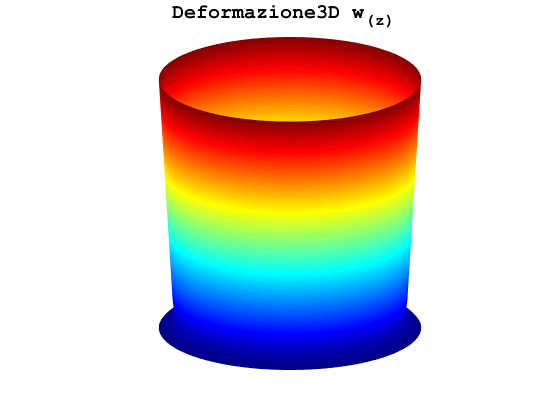

figure(2)
fig = gcf; % current figure handle
fig.Color = [1 1 1];
fig.ToolBar = 'none';
colormap(jet(100))
c=100000; % coefficiente che amplifica la deformazione
w1_n=R_n+(double(w_n(a))*c);
[X,Y,Z]=cylinder(w1_n,100);
s1=surface(X,Y,Z,'FaceAlpha',1,'EdgeColor','k','LineWidth',0.01);
title(['\fontname{Courier}\fontsize{15}Deformazione3D w_(_z_) '],'color','K');
axis off
axis square
shading interp;
view([5.700 18.800])
rotate3d

## Calcolo CDS

ns(z)=simplify(-w*E*t/R)

$$ns(z) = -\frac{\text{E}\,t\,\left(A_{1}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\cos\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)+A_{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\sin\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)-\frac{R^{2}\,\gamma \,\left(h-z\right)}{\text{E}\,t}\right)}{R}$$

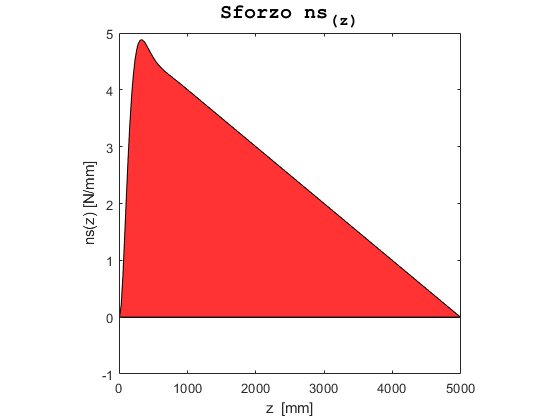

%% Plot the ns(z) stresses
a=0:h_n/(200-1):h_n;
figure(3)
area(a,double(-w_n(a)*E_n*t_n/R_n),'FaceColor','r','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo ns_(_z_)'],'color','K');
xlabel('z  [mm]');
ylabel('ns(z) [N/mm]');
axis square


w_zz(z)=simplify(diff(w_z,z))

$$w\_zz(z) = -\frac{\beta^{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\left(A_{2}\,\cos\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)-A_{1}\,\sin\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)\right)}{R^{2}}$$

mz(z)=simplify(-D*w_zz)

$$mz(z) = \frac{\text{D}\,\beta^{2}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\beta \,z}{2\,R}}\,\left(A_{2}\,\cos\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)-A_{1}\,\sin\left(\frac{\sqrt{2}\,\beta \,z}{2\,R}\right)\right)}{R^{2}}$$

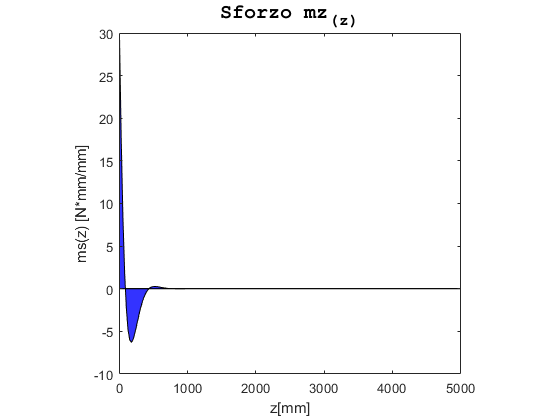

%% Plot the mz(z) stresses
figure(4)
mz_n(z)=(-wn_zz*D_n);
area(a,double(mz_n(a)),'FaceColor','b','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo mz_(_z_)'],'color','K');
xlabel('z[mm]');
ylabel('ms(z) [N*mm/mm]');
axis square



tz(z)=simplify(diff(mz))

$$tz(z) = \begin{array}{l} -\frac{\sqrt{2}\,\text{D}\,\beta^{3}\,{\mathrm{e}}^{-\sigma_{1}}\,\left(A_{1}\,\cos\left(\sigma_{1}\right)+A_{2}\,\cos\left(\sigma_{1}\right)-A_{1}\,\sin\left(\sigma_{1}\right)+A_{2}\,\sin\left(\sigma_{1}\right)\right)}{2\,R^{3}}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\beta \,z}{2\,R} \end{array}$$

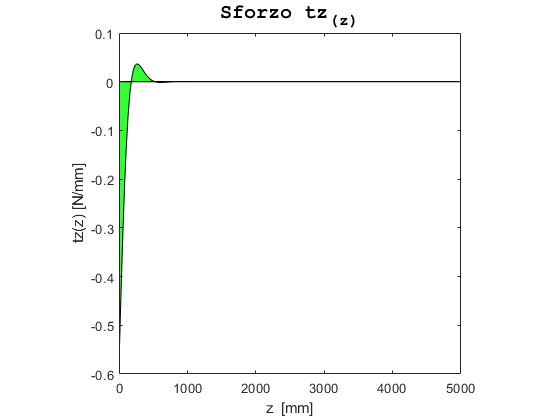

%% Plot the ns(z) stresses
figure(5)
tz_n(z)=diff(mz_n);
area(a,double(tz_n(a)),'FaceColor','g','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo tz_(_z_)'],'color','K');
xlabel('z  [mm]');
ylabel('tz(z) [N/mm]');
axis square